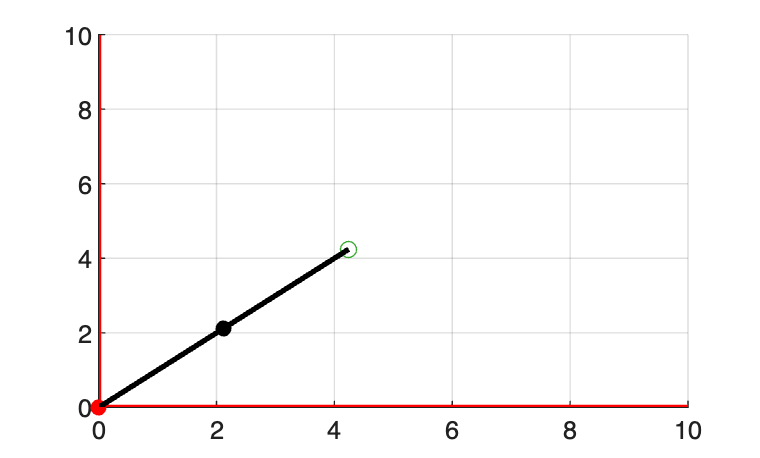




    %articulaciones
    %articulacion 1
    l1 = input("Longitud del eslabon 1(m): ");
    theta1 = input("Angulo theta 1(rad): ");
    

    %articulacion 2
    l2 = input("Longitud del eslabon 2(m): ");
    theta2 = input("Angulo theta 2(rad): ");
    
   
%bucle for para la animacion

% PRIMER MOVIMIENTO
% Los dos eslabones se mueven

for i = 0:0.1:1
    
    clf

    %ejes
line ([0 10], [0 0], [0 0], 'LineWidth',2, 'Color','red');
line ([0 0], [0 10], [0 0], 'LineWidth',2, 'Color', 'red');
hold on 
grid on


    angulo1 = theta1 * i;

    %eslabon1
    l1x = l1*cos(angulo1);
    l1y = l1*sin(angulo1);
    joint1 = [0 0]';
    joint2 = [l1x l1y]';
    scatter(joint1(1), joint1(2), 'filled', 'red');
    scatter(l1x, l1y, 'filled', 'black');

    %eslabon2
    l2x = l2*cos(angulo1);
    l2y = l2*sin(angulo1);
    EF = [l1x+l2x l1y+l2y]';
    scatter(EF(1), EF(2));

     %dibujando eslabones
    line([joint1(1) joint2(1)], [joint1(2) joint2(2)], 'linewidth', 2, 'color', 'black');
    line([joint2(1) EF(1)], [joint2(2) EF(2)], 'LineWidth',2, 'Color','black');
hold on
   
    drawnow
    pause(0.2);
end
hold on

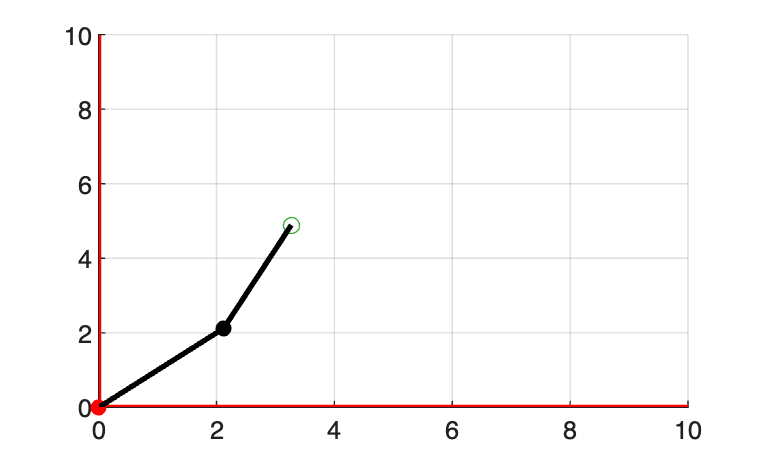

%para el segundo eslabon
for i = 0:0.1:1
    clf


    %ejes
line ([0 10], [0 0], [0 0], 'LineWidth',2, 'Color','red');
line ([0 0], [0 10], [0 0], 'LineWidth',2, 'Color', 'red');
hold on 
grid on
    angulo1 = theta1;
    angulo2 = theta2 * i;

    %eslabon1
    l1x = l1*cos(angulo1);
    l1y = l1*sin(angulo1);
    joint1 = [0 0]';
    joint2 = [l1x l1y]';
    scatter(joint1(1), joint1(2), 'filled', 'red');
    scatter(l1x, l1y, 'filled', 'black');
    
     %eslabon2
    l2x = l2*cos(angulo1 + angulo2);
    l2y = l2*sin(angulo1 + angulo2);
    EF = [l1x+l2x l1y+l2y]';
    scatter(EF(1), EF(2));

    %dibujando eslabones
    line([joint1(1) joint2(1)], [joint1(2) joint2(2)], 'linewidth', 2, 'color', 'black');
    line([joint2(1) EF(1)], [joint2(2) EF(2)], 'LineWidth',2, 'Color','black');
hold on
   
    drawnow
    pause(0.2);


end 